# A Survey of US COVID Deaths Forecasting

Many models have been proposed for forecasting deaths due to COVID in the states of the US. Here we present a comparison of the forecasts generated by the following models, including our own. The following models have been considered:

- Covid19Sim_Simulator:  [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/Covid19Sim-Simulator](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/Covid19Sim-Simulator)

- YYG-ParamSearch: [https://github.com/youyanggu/covid19_projections](https://github.com/youyanggu/covid19_projections)

- IowaStateLW_STEM: [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/IowaStateLW-STEM](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/IowaStateLW-STEM)

- CovidActNow: [https://github.com/covid-projections/covid-data-model](https://github.com/covid-projections/covid-data-model)

- UCLA_SuEIR: [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/UCLA-SuEIR](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed/UCLA-SuEIR)

- JHU_IDD: [https://github.com/HopkinsIDD/COVIDScenarioPipeline](https://github.com/HopkinsIDD/COVIDScenarioPipeline)

- CU _SELECT: [https://github.com/shaman-lab/COVID-19Projection](https://github.com/shaman-lab/COVID-19Projection)

- **[Our Model] SIkJ**$\alpha$ : [https://github.com/scc-usc/ReCOVER-COVID-19](https://github.com/scc-usc/ReCOVER-COVID-19)

These methods are evaluated on JHU dataset ([https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)) 

The chosen evaluation metric is Root Mean Squared Error (RMSE) of weekly new deaths computed over the next two weeks from the day of the forecasts.

## Load US data from all sources (JHU, NYT, USF)

clc, clear all, close all
warning off;
addpath('./hyper_params/');
load_data_us;

## Identify days to evaluate on and classify methods based on datasets


lastday = 178; % There is a file naming error, so it names them a day ahead. This will be corrected when loading.
firstday = 108;
skipdays = 7;

time_stamps =(firstday:lastday);

data_src = {'JHU'}; % Next we list methods that use these data sources in order
method_list{1} = {'Covid19Sim_Simulator'; 'YYG_ParamSearch'; 'CovidActNow_SEIR_CAN'; 'UCLA_SuEIR'; 'IowaStateLW_STEM'; 'JHU_IDD_CovidSP'; 'CU_select'; 'SIkJa_USC'};

method_descs = {'An interactive tool developed by researchers at Mass General Hospital, Harvard Medical School, Georgia Tech and Boston Medical Center.'; ...
    'Based on the SEIR model to make daily projections regarding COVID-19 infections and deaths in 50 US states. The model''s contributor is Youyang Gu.';...
    'SEIR model by the CovidActNow research team.'; ...
    'SEIR model by UCLA Statistical Machine Learning Lab.'; ...
    'A COVID19 forecast project led by Lily Wang in Iowa State University.'; ...
    'County-level metapopulation model by Johns Hopkins ID Dynamics COVID-19 Working Group.'; ...
    'A metapopulation county-level SEIR model by Columbia University.'; ...
    'This is our SI-kJalpha model.'; ...
    };

method_links = {'https://covid19sim.org/';...
    'http://covid19-projections.com/about/'; ...
    'https://covidactnow.org/'; ...
    'https://covid19.uclaml.org/'; ...
    'https://covid19.stat.iastate.edu'; ...
    'https://github.com/HopkinsIDD/COVIDScenarioPipeline'; ...
    'https://blogs.cuit.columbia.edu/jls106/publications/covid-19-findings-simulations/'; ...
    'https://scc-usc.github.io/ReCOVER-COVID-19/'};

## Load others forecasts from files

for ml_idx = 1:length(method_list)
    methods = method_list{ml_idx};
    for mm = 1:length(methods)-1
        for tt = 1:length(time_stamps)
            try
                fname = [methods{mm}, '_', num2str(time_stamps(tt)+1), '.csv'];
                preds = readtable(['../results/others_death_forecasts/', fname]);
                preds = preds{2:end, 4:end};
                if size(preds, 2) > 13
                    preds = [sum(preds(:, 1:7), 2) sum(preds(:, 8:14), 2)];
                end
                eval([methods{mm}, '{',  num2str(tt),'} = ', 'preds;']);
            catch
                eval([methods{mm}, '{',  num2str(tt),'} = ', '-1;']);
            end
        end
    end
end


## Set inputs.

horizon = 20;
dalpha  = 1;
dhorizon = horizon; % days of deaths predcitions
un = 20;
T_val = 14; % For error calculation
passengerFlow = 0;

## Load own results

for tt = 1:skipdays:length(time_stamps) % Pick some days and generate forecasts
    forecast_date = datetime(2020, 1, 23)+caldays(time_stamps(tt));
    path = '../results/historical_forecasts/';
    dirname = datestr(forecast_date, 'yyyy-mm-dd');
    fullpath = [path dirname];
    
    dtab = readtable([fullpath '/' prefix '_forecasts_deaths.csv']);
    death_pred = dtab{2:end, 3:end};
    SIkJa_USC{tt} = [death_pred(:, 8) - death_pred(:, 1), death_pred(:, 15) - death_pred(:, 8)];
    fprintf('.');
end

...........

## Evaluate all models

We evaluate RMSE as well as symmetric MAPE, however, MAPE is likely to skew the evaluation due to higher error on close-to-zero values. One may choose to ignore computing errors on values that are too small. By default, nothing is ignored. One can select a different value of "filterval" below.

filterval = 0;  
methods = method_list{1};
    for mm = 1:length(methods)
        eval(['MSE_' methods{mm}, ' = -1*ones(length(time_stamps), 1);']);
        eval(['listMSE_' methods{mm},' = -1*ones(length(countries), length(time_stamps));']);
        for tt = 1:length(time_stamps)
            eval(['preds = ' methods{mm}, '{',  num2str(tt),'};']);
            gt = [deaths(:, time_stamps(tt)+7) - deaths(:, time_stamps(tt)), deaths(:, time_stamps(tt)+14) - deaths(:, time_stamps(tt)+7)];
            
            eval(['preds = ', methods{mm}, '{',  num2str(tt),'};']);
            if length(preds)<=1
                continue;
            end
            preds = (preds + abs(preds))/2; % Replace negative values by 0
            
            cidx = all(gt > filterval, 2); % Ignore consistenty low values. Only pick high values
            cidx([51, 52, 53, 55, 56]) = 0; % We do not evaluate on these regions as not all models have provided results for these
                        
            [meanMSE, meanMAPE, listMSE] = calc_errors(gt(cidx, 1:2), preds(cidx, 1:2)); %
            
            eval(['MSE_' methods{mm}, '(',  num2str(tt),') = meanMSE;']);
            eval(['MAPE_' methods{mm}, '(',  num2str(tt),') = meanMAPE;']);
            eval(['listMSE_' methods{mm}, '(cidx, ',  num2str(tt),') = listMSE;']);
        end
    end

## Present results

Here we present the rankings.

    methods = method_list{1};
    res_avg = zeros(length(methods), 1);
    res_lat = zeros(length(methods), 1);
    for mm = 1:length(methods)
        eval(['preds = ', methods{mm}, '{',  num2str(tt),'};']);
        eval(['meanMSE = MSE_' methods{mm} ';']);
        meanMSE(meanMSE<0) = NaN;
        res_avg(mm) = nanmean(meanMSE);
        res_lat(mm) = meanMSE(end);
    end
    disp('Running Average Performance');

Running Average Performance


   [~, idx] = sort(res_avg);
    for mm = 1:length(methods)
        disp([num2str(mm) '. ' methods{idx(mm)} ' (RMSE =' num2str(res_avg(idx(mm))) ')']);
        
    end

1. SIkJa_USC (RMSE =38.9313)
2. YYG_ParamSearch (RMSE =39.1736)
3. Covid19Sim_Simulator (RMSE =55.5095)
4. UCLA_SuEIR (RMSE =69.8719)
5. CU_select (RMSE =78.2557)
6. JHU_IDD_CovidSP (RMSE =96.4873)
7. IowaStateLW_STEM (RMSE =98.0133)
8. CovidActNow_SEIR_CAN (RMSE =111.1878)


    % Generate string for leaderboard javascript
    runav_string = sprintf('runningAvgRankings: [\n');
    for mm = 1:length(methods)
        if ~isnan(res_avg(idx(mm)))
            rmse_string = num2str(round(res_avg(idx(mm)), 2));
        else
            rmse_string = '"N/A"';
        end
        runav_string = sprintf('%s\t{\n\t model: {\n name: "%s",\n description: "%s",\n link: "%s"\n},\n RMSE: %s\n},', ...
            runav_string, methods{idx(mm)}, method_descs{idx(mm)}, method_links{idx(mm)}, rmse_string);
    end
    runav_string = sprintf('%s],\n', runav_string);
    
    disp(['Recent Performance (' datestr(datenum(2020, 1, 22)+lastday) ')']);

Recent Performance (18-Jul-2020)


    [~, idx] = sort(res_lat);
    for mm = 1:length(methods)
        disp([num2str(mm) '. ' methods{idx(mm)} ' (RMSE =' num2str(res_lat(idx(mm))) ')']);
    end

1. SIkJa_USC (RMSE =42.0133)
2. YYG_ParamSearch (RMSE =44.7005)
3. UCLA_SuEIR (RMSE =56.28)
4. Covid19Sim_Simulator (RMSE =59.593)
5. JHU_IDD_CovidSP (RMSE =64.113)
6. CU_select (RMSE =65.4539)
7. IowaStateLW_STEM (RMSE =71.2827)
8. CovidActNow_SEIR_CAN (RMSE =NaN)


    % Generate string for leaderboard javascript
    runav_string1 = runav_string;
    runav_string = sprintf('recentRankings: [\n');
    for mm = 1:length(methods)
        if ~isnan(res_avg(idx(mm)))
            rmse_string = num2str(round(res_lat(idx(mm)), 2));
        else
            rmse_string = '"N/A"';
        end
        runav_string = sprintf('%s\t{\n\t model: {\n name: "%s",\n description: "%s",\n link: "%s"\n},\n RMSE: %s\n},', ...
            runav_string, methods{idx(mm)}, method_descs{idx(mm)}, method_links{idx(mm)}, rmse_string);
    end
    runav_string = sprintf('%s]', runav_string);
    disp([runav_string1 runav_string]);

runningAvgRankings: [
	{
	 model: {
 name: "SIkJa_USC",
 description: "This is our SI-kJalpha model.",
 link: "https://scc-usc.github.io/ReCOVER-COVID-19/"
},
 RMSE: 38.93
},	{
	 model: {
 name: "YYG_ParamSearch",
 description: "Based on the SEIR model to make daily projections regarding COVID-19 infections and deaths in 50 US states. The model's contributor is Youyang Gu.",
 link: "http://covid19-projections.com/about/"
},
 RMSE: 39.17
},	{
	 model: {
 name: "Covid19Sim_Simulator",
 description: "An interactive tool developed by researchers at Mass General Hospital, Harvard Medical School, Georgia Tech and Boston Medical Center.",
 link: "https://covid19sim.org/"
},
 RMSE: 55.51
},	{
	 model: {
 name: "UCLA_SuEIR",
 description: "SEIR model by UCLA Statistical Machine Learning Lab.",
 link: "https://covid19.uclaml.org/"
},
 RMSE: 69.87
},	{
	 model: {
 name: "CU_select",
 description: "A metapopulation county-level SEIR model by Columbia University.",
 link: "https://blogs.cuit.columb

## Plot all in one

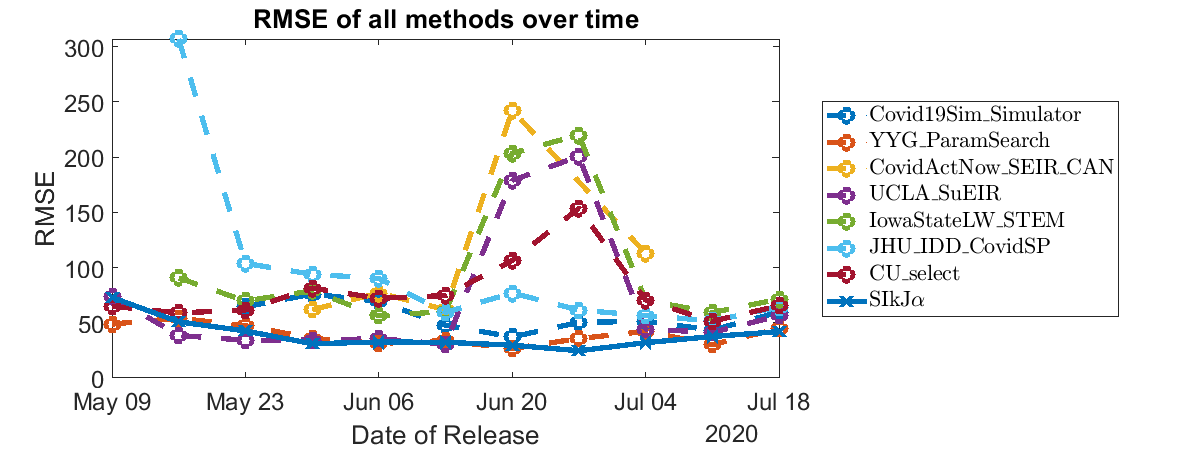

ll = [];
figure('DefaultAxesFontSize',18);
%axes('Position',[0.15 0.15 0.7 0.7])
set(gcf,'position',[10,10,1200,450]);

    methods = method_list{1};
    for mm = 1:length(methods)-1
        for tt = 1:length(time_stamps)
            try
            eval(['meanMSE(tt) = MSE_' methods{mm} '(' num2str(tt) ');']);
            eval(['meanMAPE(tt) = MAPE_' methods{mm} '(' num2str(tt) ');']);
            end
        end
        meanMSE(meanMSE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
    end
    ll = [ll; methods(1:end-1)];


        for tt = 1:length(time_stamps)
            eval(['meanMSE(tt) = MSE_SIkJa(' num2str(tt) ');']);
            eval(['meanMAPE(tt) = MAPE_SIkJa(' num2str(tt) ');']);
        end
        meanMSE(meanMSE < 0) = NaN;
        nnanidx = ~isnan(meanMSE);
        Tx = datetime(2020, 1, 22)+ caldays(time_stamps);
        plot(Tx(nnanidx), meanMSE(nnanidx), 'Marker', 'x', 'LineWidth', 4, 'MarkerSize', 10); hold on;
        ll = [ll; {['SIkJa']}];

title(['RMSE of all methods over time']);
xlabel('Date of Release');
ylabel('RMSE');
ylim([0, Inf]);
ll = strrep(ll, '_', '\_');
ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
legend(ll, "Interpreter","latex", 'location', 'eastoutside');

hold off;